# Distributed approach

rng('default');
clear;

## Settings

addpath('utils/visualization/');
addpath('utils/colors');
addpath('utils/settings');

make_settings("DataType", "condo", "PriceType", "enel")
load('settings.mat');
load('colors.mat');

plotter = Plotter(T);

#### Power generation and demand

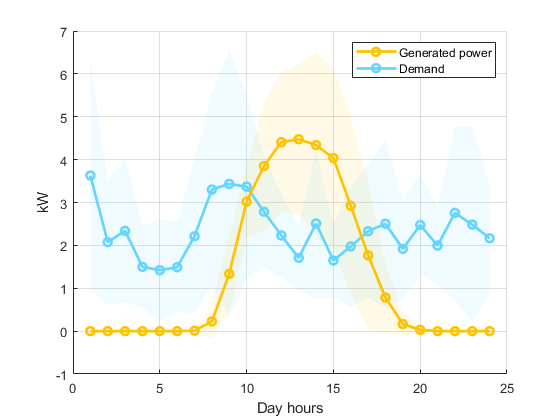

plotter.doublePlot(avg_PV, std_PV, avg_DP, std_DP, 2, 2, "-o", "-o", ...
                   colors.generation, colors.demand, ...
                   "Day hours", "kW", "Generated power", "Demand");

## Optimization problem

### Graph

adj  = ones(P,S);
cadj = mod(adj + 1, 2);  

### Settings

s_init = zeros(P, S);   % Initial storage state overwritten
b_init = s_init;        % Initial battery state overwritten

ITER   = 150;            % Number of iteration
Lambda = zeros(P, S, T); % Lagrange multipliers matrix (d_up - q_down)
Psi    = zeros(P, S, T); % Lagrange multipliers matrix (d_down - q_up)
chi    = 0.5;            % Convergence coefficient
ro     = 2;
gamma  = 1;

options = optimoptions('quadprog', 'Display', "off");

prosumer_time = zeros(1, P*ITER);
provider_time = zeros(1, S*ITER);

### History

hist.prov_cost     = zeros(ITER, S);        % Providers cost function
hist.pros_cost     = zeros(ITER, P);        % Providers cost function
hist.constr_Lambda = zeros(ITER, P,S,T);    % Constraints value (Lambda)
hist.constr_Psi    = zeros(ITER, P,S,T);    % Constraints value (Psi)
hist.pros_x        = zeros(P, 2*T + 3*T*S); % Prosumer variables
hist.prov_x        = zeros(S, 3*P*T);       % Provider variables

### Algorithm

#### Prosumers problem

Invariant terms of the *prosumers* problem

% (Prosumers) Equality constraints K_P matrix and k_P vector
K = -eye(T) + diag(alpha*ones(1,T-1),-1);
k = [zeros(1, T-1) 1];

% (Prosumers) Inquality constraints matrix
pros_B = [eye(T) zeros(T) zeros(T,T*S) zeros(T,T*S) zeros(T,T*S);  
          zeros(T) eye(T) zeros(T,T*S) zeros(T,T*S) zeros(T,T*S); 
          zeros(T*S,T) zeros(T*S,T) eye(T*S) zeros(T*S) zeros(T*S); 
          zeros(T*S,T) zeros(T*S,T) zeros(T*S) eye(T*S) zeros(T*S)];

% (Prosumers) Inquality constraints vector
pros_b = [ones(T, 1) * p_max;
          ones(T, 1) * p_max; 
          ones(T*S, 1) * d_max; 
          ones(T*S, 1) * d_max];

% (Prosumers) Lower bound vector
pros_l = zeros(1, 2*T + 3*T*S);

#### Providers problem

Invariant terms of the *providers* problem

% (Providers) Lower bound vector
prov_l = zeros(1, 3*T*P);

prov_B = [eye(T*P) zeros(T*P) zeros(T*P);
          zeros(T*P) eye(T*P) zeros(T*P);
          zeros(T,T*P) zeros(T,T*P) kron(ones(1,P), eye(T))];

#### Iterative process

for tau=1:ITER
    
    q_up   = zeros(P, S, T); % (Provider)
    q_down = zeros(P, S, T); % (Provider) 
    d_up   = zeros(P, S, T); % (Prosumer)
    d_down = zeros(P, S, T); % (Prosumer)
    
    prev_q_up   = zeros(P, S, T); % (Provider, prev. iter.)
    prev_q_down = zeros(P, S, T); % (Provider, prev. iter.)
    prev_d_up   = zeros(P, S, T); % (Prosumer, prev. iter.) 
    prev_d_down = zeros(P, S, T); % (Prosumer, prev. iter.) 
    
    % Prosumers loop
    for i=1:P
        start_prosumer_time = tic();
        
        vec_Lambda = reshape(squeeze(Lambda(i,:,:))', 1, []);
        vec_Psi    = reshape(squeeze(Psi(i,:,:))', 1, []);
        
        vec_prev_d_up   = reshape(squeeze(prev_d_up(i,:,:))', 1, []);
        vec_prev_d_down = reshape(squeeze(prev_d_down(i,:,:))', 1, []);
        
        % (Prosumers) Objective function matrix
        pros_H = diag([csi(i)*ones(1,T) csi(i)*ones(1,T) (csi(i) + ro)*ones(1,T*S) (csi(i) + ro)*ones(1,T*S) zeros(1,T*S)]);
        
        % (Prosumers) Objective function vector
        pros_f = [C -R vec_Lambda-ro*vec_prev_d_up vec_Psi-ro*vec_prev_d_down kron(ones(1,S), L)];
        
        % (Prosumers) Equality constraints matrix
        pros_A = [eye(T) -eye(T) kron(adj(i,:), eye(T)) -kron(adj(i,:), eye(T)) zeros(T, T*S);
                  zeros(T*S,T) zeros(T*S,T) -Eff_dis*eye(T*S) Eff_ch*eye(T*S) kron(eye(S), K);
                  zeros(S,T) zeros(S,T) zeros(S,T*S) zeros(S,T*S) kron(eye(S), k);
                  zeros(T*S,T) zeros(T*S,T) kron(diag(cadj(i,:)), eye(T)) zeros(T*S) zeros(T*S);
                  zeros(T*S,T) zeros(T*S,T) zeros(T*S) kron(diag(cadj(i,:)), eye(T)) zeros(T*S)];
              
        % (Prosumers) Equality constraints vector
        pros_a = [DP(i,:)' - PV(i,:)'; 
                  kron(s_init(i,:), [-alpha zeros(1,T-1)])';
                  s_init(i,:)'
                  zeros(T*S,1);
                  zeros(T*S,1)];
        
        % (Prosumers) Solve the problem for the i-th prosumer
        [pros_x, pros_cost] = quadprog(pros_H, pros_f, pros_B, pros_b, pros_A, pros_a, pros_l, [], [], options);
        
        % (Prosumers) Update charge and discharge
        d_up(i,:,:)   = reshape(pros_x(2*T+1 : 2*T+T*S), T, S)';
        d_down(i,:,:) = reshape(pros_x(2*T+T*S+1 : 2*T+2*T*S), T, S)';
        
        % (Prosumers) Update history
        hist.pros_cost(tau, i) = pros_cost;
        hist.pros_x(i, :)      = pros_x;
        
        prosumer_time(P*k + i) = toc(start_prosumer_time);
    end
   
    % Providers loop
    for j=1:S
        start_provider_time = tic();
        
        vec_Lambda = reshape(squeeze(Lambda(:,j,:))', 1, []);
        vec_Psi    = reshape(squeeze(Psi(:,j,:))', 1, []);
        
        vec_prev_q_up   = reshape(squeeze(prev_q_up(:,j,:))', 1, []);
        vec_prev_q_down = reshape(squeeze(prev_q_down(:,j,:))', 1, []);
        
        % (Providers) Objective function matrix 
        prov_H = [(zeta(j)+ro)*eye(T*P) zeta(j)*eye(T*P)      zeros(T*P);
                  zeta(j)*eye(T*P)      (zeta(j)+ro)*eye(T*P) zeros(T*P);
                  zeros(T*P)          zeros(T*P)          zeros(T*P)];

        % (Providers) Objective function vector
        prov_f = [-vec_Psi-ro*vec_prev_q_up -vec_Lambda-ro*vec_prev_q_down -kron(ones(1,P), L)];
        
        % (Providers) Equality constraint matrix
        prov_A = [Eff_ch*eye(T*P) -Eff_dis*eye(T*P) kron(eye(P), K);
                  kron(diag(cadj(:,j)), eye(T)) zeros(T*P) zeros(T*P);
                  zeros(T*P) kron(diag(cadj(:,j)), eye(T)) zeros(T*P)];

        % (Providers) Equality constraint vector
        prov_a = [kron(b_init(:,j)', [-alpha zeros(1,T-1)])';
                  zeros(T*P,1);
                  zeros(T*P,1)];
        
        % (Providers) Inequality constraints vector
        prov_b = [ones(T*P,1) * q_max;
                  ones(T*P,1) * q_max;
                  ones(T,1) * b_max(j)];
        
        % (Providers) Solve the problem for the j-th provider
        [prov_x, prov_cost] = quadprog(prov_H, prov_f, prov_B, prov_b, prov_A, prov_a, prov_l, [], [], options);
        
        % (Providers) Update battery level
        q_up(:,j,:)   = reshape(prov_x(1 : T*P), T, P)';
        q_down(:,j,:) = reshape(prov_x(T*P+1 : 2*T*P), T, P)';
        
        % (Providers) Update history
        hist.prov_cost(tau, j) = prov_cost;
        hist.prov_x(j, :)    = prov_x;
        
        provider_time(P*k + j) = toc(start_provider_time);
    end
    
    d_up   = gamma*d_up + (1 - gamma)*prev_d_up;
    d_down = gamma*d_down + (1 - gamma)*prev_d_down;
    q_up   = gamma*q_up + (1 - gamma)*prev_d_up;
    q_down = gamma*q_down + (1 - gamma)*prev_d_up;
    
    prev_d_up   = d_up;
    prev_d_down = d_down;
    prev_q_up   = q_up;
    prev_q_down = q_down;
    
    constr_Lambda = d_up - q_down;
    constr_Psi    = d_down - q_up;
    
    Lambda = Lambda + chi.*constr_Lambda;
    Psi    = Psi + chi.*constr_Psi;
    hist.constr_Lambda(tau,:,:,:) = constr_Lambda;
    hist.constr_Psi(tau,:,:,:)    = constr_Psi;
end

prosumer_mean_elapsed_time = mean(prosumer_time)

prosumer_mean_elapsed_time = 0.0023

provider_mean_elapsed_time = mean(provider_time)

provider_mean_elapsed_time = 0.0048

## Results

### Gathering variables

% Prosumers variables
distrib.var.p_up   = hist.pros_x(:,1:T);
distrib.var.p_down = hist.pros_x(:,T+1 : 2*T);
d_up               = hist.pros_x(:,2*T+1 : 2*T+T*S);
d_down             = hist.pros_x(:,2*T+T*S+1 : 2*T+2*T*S);
distrib.var.s      = sum(reshape(hist.pros_x(:,2*T+2*T*S+1 : end), P, T, S), 3);

% Providers variables
q_up          = hist.prov_x(:,1 : T*P);
q_down        = hist.prov_x(:,T*P+1 : 2*T*P);
distrib.var.b = sum(reshape(hist.prov_x(:,2*T*P+1 : end), S, T, P), 3);

% Shrink neighbors-dependant variables
distrib.var.d_up   = sum(reshape(d_up, P, T, S), 3);
distrib.var.d_down = sum(reshape(d_down, P, T, S), 3);

distrib.var.q_up   = sum(reshape(q_up, S, T, P), 3);
distrib.var.q_down = sum(reshape(q_down, S, T, P), 3);

### Gathering parameters

distrib.par.L    = L;
distrib.par.C    = C;
distrib.par.R    = R;
distrib.par.zeta = zeta;
distrib.par.csi  = csi;

### Lagrangian multiplier convergence

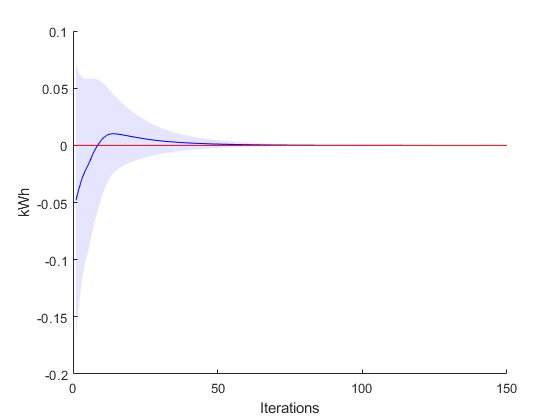

constr = [hist.constr_Lambda hist.constr_Psi];

avg_constr = mean(constr, [2 3 4])';
std_constr = std(constr, 0, [2 3 4])';

plotter.plotConvergence(avg_constr, std_constr, ITER);

### Power bought

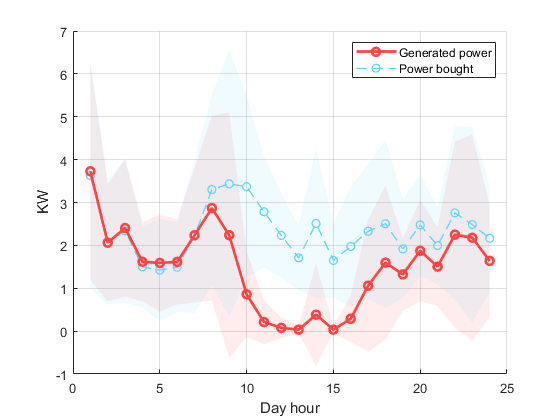

avg_p_up = mean(distrib.var.p_up, 1);
std_p_up = std(distrib.var.p_up, 0, 1);

plotter.doublePlot(avg_p_up, std_p_up, avg_DP, std_DP, 2, 1, "-o", "--o", ...
                   colors.retailer, colors.demand, ...
                   "Day hour", "KW", "Power bought", "Demand");

### Power sold

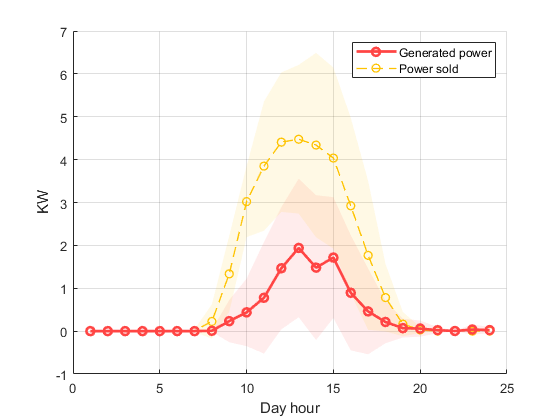

avg_p_down = mean(distrib.var.p_down, 1);
std_p_down = std(distrib.var.p_down, 0, 1);

plotter.doublePlot(avg_p_down, std_p_down, avg_PV, std_PV, 2, 1, "-o", "--o", ...
                   colors.retailer, colors.generation, ...
                   "Day hour", "KW", "Power sold", "Generated power");

### Battery and storage state

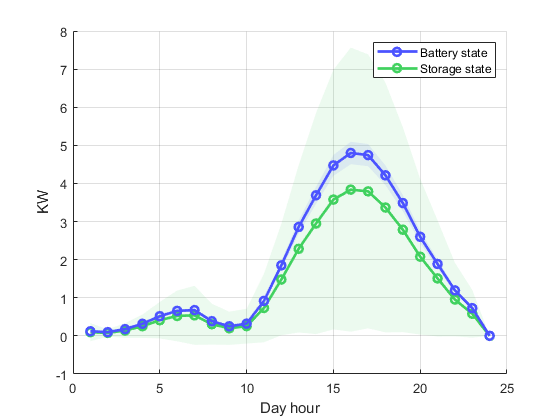

avg_b = mean(distrib.var.b, 1);
std_b = std(distrib.var.b, 0, 1);

avg_s = mean(distrib.var.s, 1);
std_s = std(distrib.var.s, 0, 1);

plotter.doublePlot(avg_b, std_b, avg_s, std_s, 2, 2, "-o", "-o", ...
                   colors.provider, colors.prosumer, ...
                   "Day hour", "KW", "Battery state", "Storage state");

### Charging and discharging dynamic

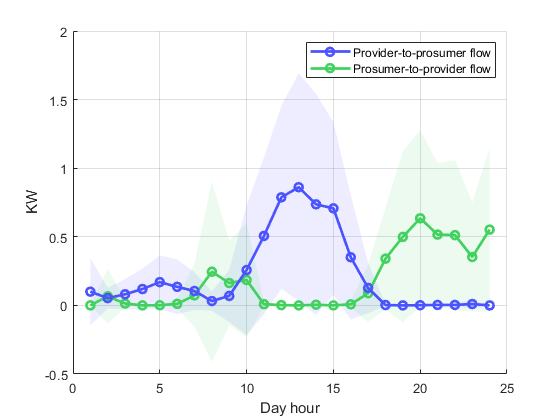

avg_d_down = mean(distrib.var.d_down, 1);
std_d_down = std(distrib.var.d_down, 0, 1);

avg_d_up = mean(distrib.var.d_up, 1);
std_d_up = std(distrib.var.d_up, 0, 1);

plotter.doublePlot(avg_d_down, std_d_down, avg_d_up, std_d_up, 2, 2, "-o", "-o", ...
                   colors.provider, colors.prosumer, ...
                   "Day hour", "KW", "Provider-to-prosumer flow", "Prosumer-to-provider flow");

### Economy summary

DistributedEconomy = economy(distrib);
DistributedEconomyTable = economy_table(DistributedEconomy)

DistributedEconomyTable = 3×6 table
                 PowerSoldRevenue    PowerBoughtCosts    PowerStoredCosts    PowerStoredRevenues    EfficiencyCosts    TotalCosts
                 ________________    ________________    ________________    ___________________    _______________    __________

    Prosumers         5.3108              22.102              20.265                    0               160.39           197.45  
    Providers              0                   0                   0                20.29               7.6281          -12.662  
    Retailer          5.3108              22.102                   0                    0                    0           16.791  


CommunityTotalCosts = sum(DistributedEconomy.Prosumers.TotalCosts) + sum(DistributedEconomy.Providers.TotalCosts)

CommunityTotalCosts = 184.7894

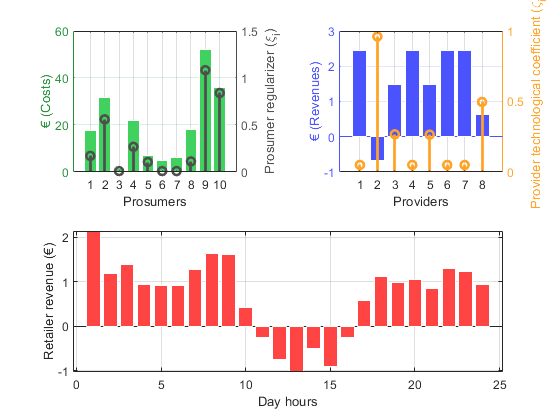


figure;
tiledlayout(2,2);

% Prosumer revenues
nexttile;
yyaxis left
ax_pros_cost = gca;
ax_pros_cost.YColor = '#23903a';
bar(DistributedEconomy.Prosumers.TotalCosts, ...
    'EdgeColor', 'w', ...
    'FaceColor', colors.prosumer.hex);
ylabel('€ (Costs)');

yyaxis right
ax_csi = gca;
ax_csi.YColor = '#4F4F4F';
stem(csi, ...
     'Color','#4F4F4F', ...
     'LineWidth', 2);
ylabel('Prosumer regularizer (\xi_i)');

grid on;
xlabel('Prosumers');

% Provider revenues
nexttile;
yyaxis left
ax_prov_cost = gca;
ax_prov_cost.YColor = colors.provider.rgb;
bar(-DistributedEconomy.Providers.TotalCosts, ...
    'EdgeColor', 'w', ...
    'FaceColor', colors.provider.rgb);
ylabel('€ (Revenues)');

yyaxis right
ax_csi = gca;
ax_csi.YColor = '#FFA326';
stem(zeta, ...
     'Color','#FFA326', ...
     'LineWidth', 2);
ylabel('Provider technological coefficient (\zeta_i)');

grid on; 
xlabel('Providers');
% Retailer revenues
nexttile([1 2]);
bar(DistributedEconomy.Retailer.HourlyRevenues, ...
    'EdgeColor', 'w', ...
    'FaceColor', colors.retailer.hex);
grid on;
ylabel('Retailer revenue (€)');
xlabel('Day hours');

### Saving results 

distrib.Economy = DistributedEconomy;
save("data/distributed.mat", "distrib");